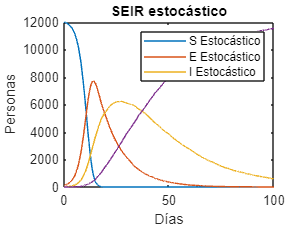


% Parámetros del modelo SEIR
beta = 2.95;    % Tasa de transmisión
sigma = 0.09;   % Tasa de incubación
gamma = 0.04;   % Tasa de recuperación
N = 12135;      % Población total
I0 = 15;        % Número inicial de infectados
E0 = 120;        % Número inicial de expuestos
R0 = 0;        % Número inicial de recuperados
S0 = 12000;  % Número inicial de susceptibles

i=1;
while i<=1
    % Tiempo total de simulación
    T = 100;
    
    % Inicializar vectores para almacenar resultados
    S = S0;
    E = E0;
    I = I0;
    R = R0;
    t = 0;
    
    S_vec = [S0];
    E_vec = [E0];
    I_vec = [I0];
    R_vec = [R0];
    t_vec = [0];
    
    while t < T
        beta_susceptibles = beta * S * I / N;
        sigma_exposed = sigma * E;
        gamma_infectious = gamma * I;
        
        total_rate = beta_susceptibles + sigma_exposed + gamma_infectious;
        
        dt = -log(rand()) / total_rate;
        
        % Determina el evento y actualiza las poblaciones
        event = rand();
        if event < beta_susceptibles / total_rate
            S = S - 1;
            E = E + 1;
        elseif event < (beta_susceptibles + sigma_exposed) / total_rate
            E = E - 1;
            I = I + 1;
        else
            I = I - 1;
            R = R + 1;
        end
        
        t = t + dt;
        
        % Almacena los valores actuales en los vectores
        S_vec = [S_vec S];
        E_vec = [E_vec E];
        I_vec = [I_vec I];
        R_vec = [R_vec R];
        t_vec = [t_vec t];
    end
    
    % Graficar resultados
    plot(t_vec, S_vec);
    hold on;
    plot(t_vec, E_vec);
    hold on
    plot(t_vec, I_vec);
    hold on
    plot(t_vec, R_vec);
    hold on

    [tm, tim] = max(E_vec);
    tt=t_vec(tim);
    i=i+1;



end


legend('S Estocástico','E Estocástico','I Estocástico')
title('SEIR estocástico')
ylabel('Personas')
xlabel('Días')
xlim([0 100])
ylim([0 12000])